# Wavelet Time Scattering for ECG Signal Classification

This example shows how to classify human electrocardiogram (ECG) signals. 

To train a deep neural network to classify sequence data, you can use an LSTM neural network. An LSTM neural network enables you to input sequence data into a network, and make predictions based on the individual time steps of the sequence data.

This diagram illustrates sequence data flowing through a sequence classification neural network.

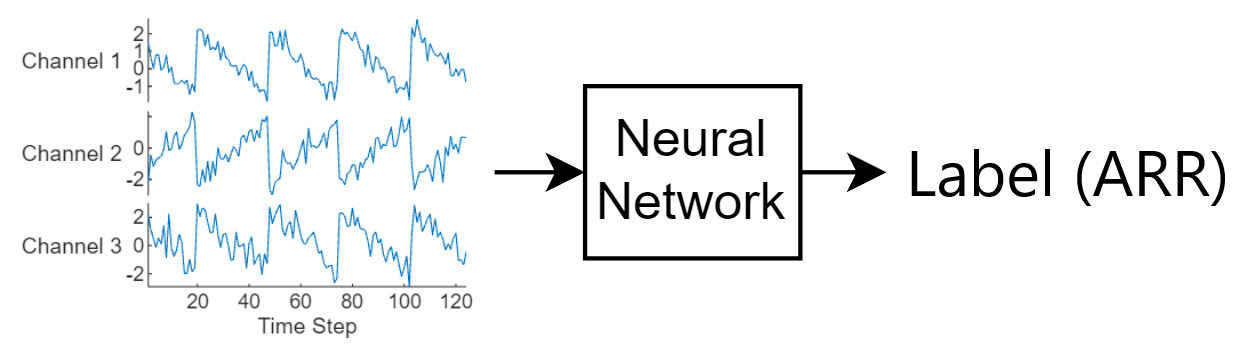

This example is adapted to use features from a wavelet transform. In wavelet scattering, data is propagated through a series of wavelet transforms, nonlinearities, and averaging to produce low-variance representations of time series. Wavelet time scattering yields signal representations insensitive to shifts in the input signal without sacrificing class discriminability. One could have tried to use the raw sequence data instead, but this is typically less efficient (longer training) 

You must have the Wavelet Toolbox™ and the Statistics and Machine Learning Toolbox™ to run this example. The data used in this example are publicly available from [PhysioNet](https://physionet.org).

The data has 816 features and 127 timesteps each.

clear
addpath(fullfile("../data"))
addpath(fullfile("../helpers"))
load("ECGData.mat")

## Data Preparation (Create Training and Test Data)

Randomly split the data into two sets - training and test data sets. The helper function `helperRandomSplit` performs the random split. `helperRandomSplit` accepts the desired split percentage for the training data and  `ECGData`. The `helperRandomSplit` function outputs two data sets along with a set of labels for each. Each row of `trainData` and `testData` is an ECG signal. Each element of `trainLabels` and `testLabels` contains the class label for the corresponding row of the data matrices. In this example, we randomly assign 70% percent of the data in each class to the training set. The remaining 30% is held out for testing (prediction) and are assigned to the test set.

percent_train = 70;
[trainData,testData,trainLabels,testLabels] = helperRandomSplit(percent_train,ECGData);
% save this output for later use in chap 3 as ECG_Data_split.mat
save(fullfile("../data/ECG_Data_split.mat"),"trainData","testData","trainLabels","testLabels");

There are 113 records in the `trainData` set and 49 records in `testData`. By design the training data contains 69.75% (113/162) of the data. Recall that the ARR class represents 59.26% of the data (96/162), the CHF class represents 18.52% (30/162), and the NSR class represents 22.22% (36/162). Examine the percentage of each class in the training and test sets. The percentages in each are consistent with the overall class percentages in the data set.

Ctrain = countcats(categorical(trainLabels))./numel(trainLabels).*100
Ctest = countcats(categorical(testLabels))./numel(testLabels).*100

## Windowed/buffered Wavelet Scattering on Input Signal (Exercise)

The key parameters to specify in a wavelet time scattering network are the scale of the time invariant, the number of wavelet transforms, and the number of wavelets per octave in each of the wavelet filter banks. In many applications, the cascade of two filter banks is sufficient to achieve good performance. In this example, we construct a wavelet time scattering network with the default filter banks: 8 wavelets per octave in the first filter bank and 1 wavelet per octave in the second filter bank. The invariance scale is set to 4 seconds.

After constructing the scattering network, obtain the scattering coefficients for the training data as a matrix. When you run `featureMatrix` with multiple signals, each column is treated as a single signal.

The output for a single signalwindow of length 1024 samples is 102x8. This output is reshaped into a vector of length 816 and the outputs of the individual signal windows are appended. This transforms the original signal into a signal of features with the dimension 127x816 (time x features).

**Exercise:** Use the function [`waveletScattering`](https://www.mathworks.com/help/releases/R2024b/wavelet/ref/waveletscattering.html) to calculate the wavelet scattering. Name the output `sn`. Use options

- SignalLength = 1024 (corresponds to 8 seconds)

- InvarianceScale = 4

- SamplingFrequency = 128

train=waveletFeatures(trainData);
test=waveletFeatures(testData);

save(fullfile("../data/LSTM_data_preprocessed.mat"),"train","test")

function feat = waveletFeatures(data)
    ds = 1024; % variable for the signallength 
    % YOUR CODE HERE
    
    %loop over the patients
    sz=size(data);
    feat{sz(1)}=[];
    parfor m=1:sz(1)
        %ws_feat=zeros(1,65536/ds/2);
        i=1;
        ws_feat=zeros(127,816);
        for n=1:ds/2:65536-ds/2
            ws_temp=featureMatrix(sn,data(m,n:n+ds-1)');
            ws_feat(i,:)=ws_temp(:);
            i=i+1;
        end
            feat{m}=ws_feat;
    end
end

## Define LSTM Neural Network Architecture

Define the LSTM neural network architecture.

- Specify the input size to be the number of channels of the input data. 

- Specify a LSTM layer with 120 hidden units, and output the last element of the sequence.

- Finally, include a fully connected layer with an output size that matches the number of classes followed by a softmax layer.

If you have access to full sequences at prediction time, then you can use a bidirectional LSTM layer in your network. A bidirectional LSTM layer learns from the full sequence at each time step. If you do not have access to the full sequence at prediction time, for example, if you are forecasting values or predicting one time step at a time, then use an LSTM layer instead.

numChannels = 816; %number of input features
numHiddenUnits = 120;
numClasses = 3;

layers = [
    sequenceInputLayer(numChannels)
    lstmLayer(numHiddenUnits,OutputMode="last")
    fullyConnectedLayer(numClasses)
    softmaxLayer]

## Specify Training Options (exercise)

Specify the training options. Choosing among the options requires empirical analysis. To explore different training option configurations by running experiments, you can use the [Experiment Manager](docid:nnet_ref#mw_11ce840f-eed7-4975-9c28-baeebd79f092) app. 

- Train using the Adam solver.

- Train for 200 epochs.

- Specify a learning rate of 0.001.

- Clip the gradients with a threshold of 1.

- To keep the sequences sorted by length, disable shuffling.

- Display the training progress in a plot and monitor the accuracy.

- Disable the verbose output.

% YOUR CODE HERE

Train the neural network using the [`trainnet`](docid:nnet_ref.mw_87a4761c-af20-4e6e-9752-e145a8295c97) function. For classification, use cross-entropy loss. This network can be trained on a desktop CPU, it should not take more than 5 minutes. By default, the `trainnet` function uses a GPU if one is available. Using a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information on supported devices, see [GPU Computing Requirements](docid:distcomp_ug.mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the function uses the CPU. To specify the execution environment, use the `ExecutionEnvironment` training option.

doTraining=true;
if doTraining
    net = trainnet(train',categorical(trainLabels),layers,"crossentropy",options);
else
    load('LSTM.mat')
end

Test the neural network using the [`testnet`](docid:nnet_ref.mw_3eb84788-36da-4e3e-a351-ecbc55b86c2b) function. For single-label classification, evaluate the accuracy. The accuracy is the percentage of correctly predicted labels. By default, the `testnet` function uses a GPU if one is available. To select the execution environment manually, use the `ExecutionEnvironment` argument of the `testnet` function.

acc = testnet(net,test',categorical(testLabels),"accuracy") 

Display the classification results in a confusion chart. Make predictions using the [`minibatchpredict`](docid:nnet_ref.mw_c7ae5ad7-5485-4270-8657-694ab264fb57) function and convert the scores to labels using the [`scores2label`](docid:nnet_ref.mw_b4669b80-206b-472f-a9eb-7e9642b3c38c) function. By default, the `minibatchpredict` function uses a GPU if one is available.

scores = minibatchpredict(net,test');
classNames = categories(categorical(testLabels));
predTest = scores2label(scores,classNames);

Display the classification results in a confusion chart. 

figure
confusionchart(categorical(testLabels),predTest)

### [Optional] Additional Information about Wavelets

The key parameters to specify in a wavelet time scattering network are the scale of the time invariant, the number of wavelet transforms, and the number of wavelets per octave in each of the wavelet filter banks. In many applications, the cascade of two filter banks is sufficient to achieve good performance. In this example, we construct a wavelet time scattering network with the default filter banks: 8 wavelets per octave in the first filter bank and 1 wavelet per octave in the second filter bank. The invariance scale is set to 150 seconds.

%create filterbank
N = size(ECGData.Data,2);
sn = waveletScattering(SignalLength=N,InvarianceScale=150, ...
    SamplingFrequency=128);
[fb,f,filterparams] = filterbank(sn);
figure
tiledlayout(2,1)
nexttile
plot(f,fb{2}.psift)
xlim([0 128])
grid on
title("1st Filter Bank Wavelet Filters")
nexttile
plot(f,fb{3}.psift)
xlim([0 128])
grid on
title("2nd Filter Bank Wavelet Filters")
xlabel("Hz")

To demonstrate the invariance scale, obtain the inverse Fourier transform of the scaling function and center it at 0 seconds in time. The two vertical black lines mark the -75 and 75 second boundaries. Additionally, plot the real and imaginary parts of the coarsest-scale (lowest frequency) wavelet from the first filter bank. Note that the coarsest-scale wavelet does not exceed the invariant scale determined by the time support of the scaling function. This is an important property of wavelet time scattering.

figure
phi = ifftshift(ifft(fb{1}.phift));
psiL1 = ifftshift(ifft(fb{2}.psift(:,end)));
t = (-2^15:2^15-1).*1/128;
scalplt = plot(t,phi);
hold on
grid on
ylim([-1.5e-4 1.6e-4])
plot([-75 -75],[-1.5e-4 1.6e-4],"k--")
plot([75 75],[-1.5e-4 1.6e-4],"k--")
xlabel("Seconds")
ylabel("Amplitude")
wavplt = plot(t,[real(psiL1) imag(psiL1)]);
legend([scalplt wavplt(1) wavplt(2)], ...
    {"Scaling Function","Wavelet-Real Part","Wavelet-Imaginary Part"})
title({"Scaling Function";"Coarsest-Scale Wavelet First Filter Bank"})
hold off

## References

This live script is based on: [https://www.mathworks.com/help/wavelet/ug/ecg-signal-classification-using-wavelet-time-scattering.html](https://www.mathworks.com/help/wavelet/ug/ecg-signal-classification-using-wavelet-time-scattering.html)

*Copyright 2018-2025 The MathWorks, Inc.*